%% step2_check_result.m
clc; clear; close all;

% 设定分辨率（需与第一步保持一致 64x64）
WIDTH  = 64;
HEIGHT = 64;
TOTAL_PIXELS = WIDTH * HEIGHT;

% 1. 读取 Verilog 仿真输出的十六进制文本
fid = fopen('C:\Users\jingzifu\Desktop\sim_out.txt', 'r');
if fid == -1
    error('未找到 sim_out.txt，请确认已将该文件复制到 MATLAB 当前工作目录下！');
end
data_hex = textscan(fid, '%s');
fclose(fid);

hex_lines = data_hex{1};
fprintf('成功读取 sim_out.txt，共读取到 %d 个像素数据（理论需要 %d 个）\n', length(hex_lines), TOTAL_PIXELS);

成功读取 sim_out.txt，共读取到 4096 个像素数据（理论需要 4096 个）


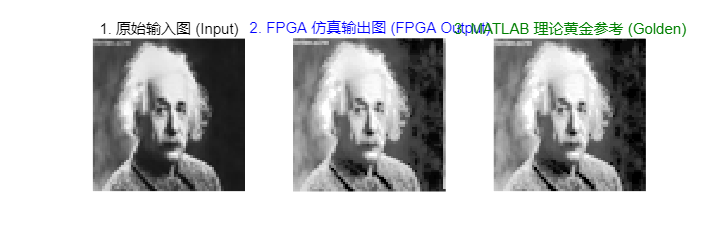


% 2. 将十六进制数据解析为 RGB 图像矩阵
img_sim = zeros(HEIGHT, WIDTH, 3, 'uint8');
for r = 1:HEIGHT
    for c = 1:WIDTH
        idx = (r - 1) * WIDTH + c;
        if idx <= length(hex_lines)
            val = hex2dec(hex_lines{idx});
            R = bitshift(bitand(val, hex2dec('FF0000')), -16);
            G = bitshift(bitand(val, hex2dec('00FF00')), -8);
            B = bitand(val, hex2dec('0000FF'));  % B 分量是低 8 位，直接与运算即可
            img_sim(r, c, 1) = uint8(R);
            img_sim(r, c, 2) = uint8(G);
            img_sim(r, c, 3) = uint8(B);
        end
    end
end

% 3. 读取原图和 MATLAB 理论黄金参考图
img_raw    = imread('C:/Users/jingzifu/Desktop/OIP.jpg'); % 替换为你自己的图片路径
img_raw    = imresize(img_raw, [HEIGHT, WIDTH]);
img_golden = imread('matlab_golden.png');

% 4. 三图并排对比显示
figure('Name', 'FPGA 图像处理算法验证', 'Position', [100, 200, 1200, 400]);

subplot(1, 3, 1);
imshow(img_raw);
title('1. 原始输入图 (Input)', 'FontSize', 12);

subplot(1, 3, 2);
imshow(img_sim);
title('2. FPGA 仿真输出图 (FPGA Output)', 'FontSize', 12, 'Color', 'b');

subplot(1, 3, 3);
imshow(img_golden);
title('3. MATLAB 理论黄金参考 (Golden)', 'FontSize', 12, 'Color', [0 0.5 0]);

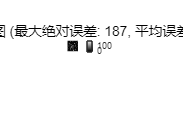


% 5. 逐像素误差分析
diff_map = abs(double(img_sim(:,:,1)) - double(img_golden(:,:,1)));
max_diff = max(diff_map(:));
mean_diff = mean(diff_map(:));

figure('Name', '误差热力图分析', 'Position', [200, 200, 600, 450]);
imshow(diff_map, []); colorbar;
title(sprintf('像素差值热力图 (最大绝对误差: %d, 平均误差: %.2f)', max_diff, mean_diff), 'FontSize', 11);


fprintf('\n============== 验证结果评估 ==============\n');


============== 验证结果评估 ==============


fprintf('最大绝对像素误差: %d (灰度级 0~255)\n', max_diff);

最大绝对像素误差: 187 (灰度级 0~255)


fprintf('平均像素误差:     %.2f\n', mean_diff);

平均像素误差:     18.44


if max_diff <= 3
    fprintf('【恭喜】FPGA 输出与理论算法几乎完全一致（微小误差源于硬件定点化截断）！\n');
elseif max_diff <= 10
    fprintf('【合格】算法基本正确，存在少量定点化/量化误差。\n');
else
    fprintf('【注意】误差较大，请检查直方图累加除法或时序打拍对齐情况。\n');
end

【注意】误差较大，请检查直方图累加除法或时序打拍对齐情况。


fprintf('=========================================\n');